# Example 2: Analysis of an .stl file.

First, define the stl file and path for the file you wish to analyse

filepathname = "data/Juicer_v01.stl"; % Full path and name of the .stl file
mytrimesh = trimesh('stl',filepathname); % Create the trimesh object from the .stl file

Calculate properties of the **trimesh** object, define which method of curvature analysis you want to use.

"**none**" will produce the fastest result but have no curvature data - this is the default, and will be used for any other input.

"**trimesh**" uses the trimeshcurvature algorithm based on the paper:  Meyer, M., Desbrun, M., Schröder, P., & Barr, A. H. (2003). Discrete differential-geometry operators for triangulated 2-manifolds. Visualization and mathematics III (pp. 35-57). Springer Berlin Heidelberg. [http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.24.3427&rep=rep1&type=pdf](http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.24.3427&rep=rep1&type=pdf)

"**patch**" uses the patch curvature function, written by D.Kroon University of Twente (August 2011) . This is based on a fitting a quadratic patch around each local vertex and it's neighbouring vertices. This is typically slower than the trimeshcurvature algorithm.

curvatureMethod = "none"; % Define which method of curvature analysis ("none", "trimesh", "patch")
mytrimesh = mytrimesh.calculateProperties(curvatureMethod);
faceProperties = fieldnames(mytrimesh.Fproperty)

faceProperties = 7×1 cell array
    {'Nx'         }
    {'Ny'         }
    {'Nz'         }
    {'inclination'}
    {'centroid'   }
    {'area'       }
    {'volume'     }


vertexProperties = fieldnames(mytrimesh.Vproperty)

vertexProperties = 7×1 cell array
    {'Nx'         }
    {'Ny'         }
    {'Nz'         }
    {'inclination'}
    {'LPBFQuality'}
    {'Ra'         }
    {'Rz'         }


## Preview the a colored trimesh

Define the **property** you wish to preview. You may use any per-face or per-vertex property within **mytrimesh**, the names of these properties may be found as the fields of **mytrimesh.Fproperty** or **mytrimesh.Vproperty **

You may specify to use "**fancy**" graphics, which will be used be default if nothing is specified.

You may also wish to pass in an **Axis**, which the trimesh will be plotted on - by default a new axis will be created for the figure.

By default, the colorbar automatically scales to capture the 1st-99th percentile data.

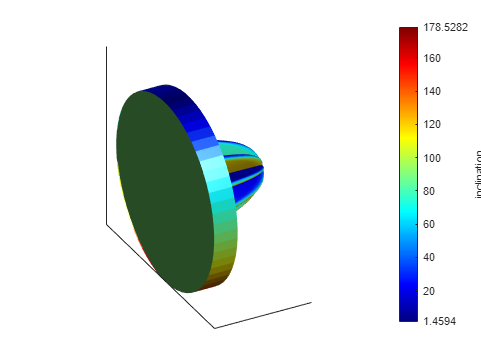

property = 'inclination'; % property name must match the string before the space character
opt.fancy = 1; % boolean 1 or 0 to turn fancy graphics on or off.
figure; ax = gca; % gca uses the current axis object
mytrimesh.plotMesh(property,opt,ax);

## Convert to field data structure

Field based, or implicit data is an alternative way to define geometry. The TPMS designer package includes utilities to convert a **trimesh** object to a **v3field** object which is a voxelised representation of the same geometry.

The user may define a voxel size, smaller numbers will result in higher computational cost, but better resolution.

If you wish to create properties, this can be done by modifying the **v3field.calculateProperties** function and saving the new properties under v3field.properties.

voxelSize = 0.5; %voxelsize in mm
myv3field=mytrimesh.getField(voxelSize);
myv3field=myv3field.calculateProperties % Call the calculate properties method to fill out property data

myv3field =   v3Field with properties:

        name: "data/Juicer_v01.stl"
       lower: [0 0 0]
       upper: [164.2874 79 149.9188]
         res: [329 158 300]
          xq: [0 0.5009 1.0018 1.5026 2.0035 2.5044 3.0053 3.5061 4.0070 4.5079 5.0088 5.5096 6.0105 6.5114 7.0123 7.5131 8.0140 8.5149 9.0158 9.5166 10.0175 10.5184 11.0193 11.5201 12.0210 12.5219 13.0228 13.5237 14.0245 14.5254 15.0263 15.5272 … ]
          yq: [0 0.5032 1.0064 1.5096 2.0127 2.5159 3.0191 3.5223 4.0255 4.5287 5.0318 5.5350 6.0382 6.5414 7.0446 7.5478 8.0510 8.5541 9.0573 9.5605 10.0637 10.5669 11.0701 11.5732 12.0764 12.5796 13.0828 13.5860 14.0892 14.5924 15.0955 15.5987 … ]
          zq: [0 0.5014 1.0028 1.5042 2.0056 2.5070 3.0084 3.5098 4.0112 4.5126 5.0140 5.5154 6.0168 6.5182 7.0196 7.5210 8.0224 8.5238 9.0252 9.5266 10.0280 10.5294 11.0308 11.5322 12.0336 12.5350 13.0364 13.5378 14.0392 14.5406 15.0420 15.5434 … ]
    property: [1×1 stru

myv3field.property

ans = struct with fields:
                    X: [158×329×300 double]
                    Y: [158×329×300 double]
                    Z: [158×329×300 double]
              surface: [158×329×300 double]
                solid: [158×329×300 double]
                    U: [158×329×300 double]
              azimuth: [158×329×300 double]
          inclination: [158×329×300 double]
    manufacturability: [158×329×300 double]


## Preview and visualise field-based properties

Similarly to visualising property of a **trimesh**, the user can visualise **v3field** properties.

You may specify a **sliceHeight** (as a percentage of the total object height) you with to preview the filed property at, this may be added/overlayed on previously made figures. Alternatively set **sliceHeight** = [] to utilise matlab's interactive orthosliceviewer.

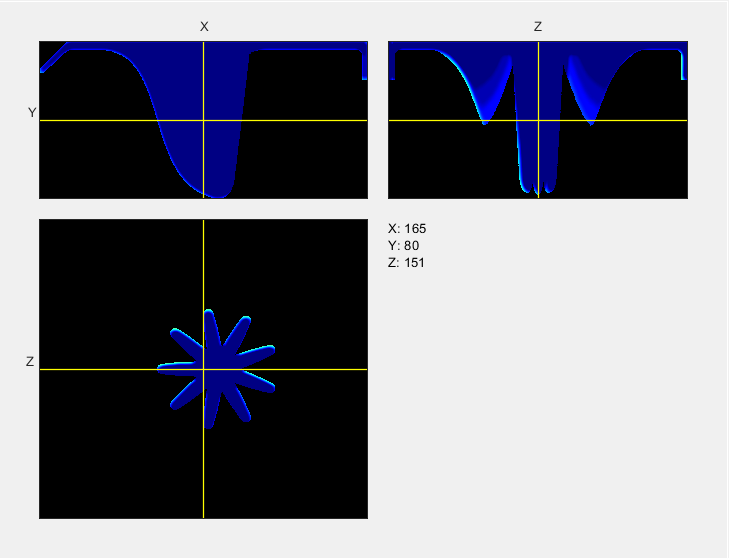

property = "manufacturability";
sliceHeight = []; 
h = myv3field.plotField(property,sliceHeight);

## Further Data Analysis

The distribution of various proeprties can also give inishgts into the performance of a component.

For example, we can look at the probability density distribution of the manufacturability index. The index is defined as -1=empty space, and solid volume ranging from 0 to 1 - where 0 is likely to fail/have problems and 1 being produced without problems.

A design which is more suited to additive manufacturing will have a distribution with a small fraction close to 0 (or volume requiring support structures).

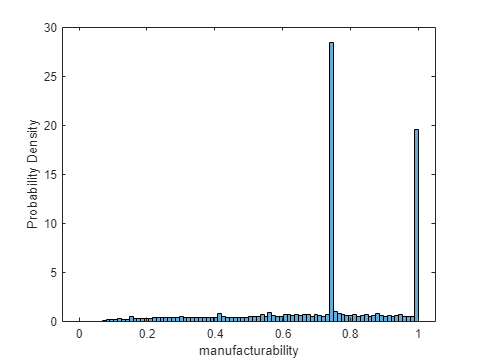

figure
temp = myv3field.property.manufacturability;
temp = temp(myv3field.property.surface==1);
histogram(temp,'BinLimits',[0 1],'Normalization',"pdf");
%set(gca, 'YScale', 'log'); grid on;
ylabel(gca,'Probability Density'); xlabel(gca,property);

## Using metrics

As the structures investigated are highly complex and are often unwieldy to asses, TPMS Designer utilises a metrics-based approach. This allows a property of a complex design to be approximated with a simplified metric - these are used heavily in **example3_DOE** to compare various properties of TPMS-like structure in a large design of experiments. 

The **metrics** class includes a predefined set of normalised sums, means, maximums or defined percentiles value of various properties, as well as some mechanical metrics for use in comparing cellular structures.

Different metrics may require different properties to be calculated for the field or surface-mesh based representation of an object.

M = metrics;
M = M.fvMetrics(mytrimesh);
M = M.mechanicalMetrics(myv3field)

M =   metrics with properties:

           CPUtime: []
            Nfaces: 27934
            Nnodes: 83802
            volume: 1.9320e+05
    volumeFraction: 0.1104
       surfaceArea: 7.6149e+04
      relativeArea: []
             rmsMC: []
             rmsGC: []
         thickness: 14.2128
      poreDiameter: 47.0397
           areaVar: 0.0069
          areaMean: 0.1091
           areaStd: 0.0832
           areaMin: 0.0179
           areaMax: 0.3076
    areaBelow30deg: 0.0924
        LpbfRa_Max: 25.1009
       LpbfRa_Mean: 4.7235
    LPBFerror_Mean: []
     LPBFerror_Max: []
           elastic: []
           poisson: []
             shear: []
    totalStiffness: []
        zenerRatio: []
         errorFlag: 0
